# 5ELEN018W Robotic Principles - Tutorial 3 

#                Pose and Transformations

## Exercise 1

Assume that the hand of a planar (2D) robot manipulator is at position *P *= [64, 71.4] relative to the robot's base reference frame fixed to the robot. The robot's reference frame has an angle $$\theta= 90^{\circ}$$ with respect to the world reference frame  and it has the same origin as the world frame origin.

Write the rotation matrix of the above transformation and apply it to point *P *to calculate its position (coordinates) with respect to the world reference coordinate frame.

P = [64
     71.4];

% assign the rotation matrix to a matrix called R below
% R = ?????

% calculate the new coordinates of P with respect to the world reference
% frame and assign them to the matrix P_new below
% P_new = ?????

### Check your answer

R = [cos(pi/2) -sin(pi/2)
    sin(pi/2)  cos(pi/2)]

R =     0.0000   -1.0000
    1.0000    0.0000



P_new = R*P

P_new =   -71.4000
   64.0000



assert(abs(sum(R(:)) - 6.1232e-17) < 0.01, 'Rotation matrix is incorrect')
assert(abs(sum(P_new(:)) + 7.4) < 0.01, 'Transformation calculation is wrong')

## Exercise 2

Prove by writing some Matlab code that the transformations in 2D space (i.e on a plane) are not commutative. That means that if you transform a point *P *to a new reference frame obtained by first translation and then rotation is not the same as with the transform obtained by first rotating and then translating the original reference frame.

Calculate the distance of the 2 points obtained by the above two transformations by using the `norm `function which calculates the Euclidean distance between 2 points in space:

[https://en.wikipedia.org/wiki/Euclidean_distance](https://en.wikipedia.org/wiki/Euclidean_distance)

theta = pi + 3*pi/8;

% Rotation matrix
R = [cos(theta) -sin(theta)  
    sin(theta)  cos(theta)];

% Translation matrix
t_x = 68;  
t_y = 99;
T = [t_x
     t_y];

% just a vector for which we would like to compute its new 
% coordinates in a new reference frame described first by a 
% rotation and then translation vs translation and then rotation
P = [4
    25];

Rot_transl = R*P + T  % first rotation then translation

Rot_transl =    89.5663
   85.7374


Transl_rot = R*(P + T)  % first translation then rotation

Transl_rot =    87.0079
 -113.9721



% Calculate the Euclidean distance between the 2 points obtained
% by the above two transformations
norm(Rot_transl-Transl_rot)

ans = 199.7259

## Exercise 3

We consider a world reference frame denoted by {0} which has its x-axis pointing east and its y-axis pointing north. There is a robot with an attached body-fixed coordinate frame {B} whose origin is in the centre of the robot, and whose *x*-axis points in the robot's forward direction.

With respect to the world frame origin , the robot's centre is at a distance of 123m in the x-direction and -74.6m in the *y*-direction. The robot's heading angle is exactly SSW.

Write a 3x3 matrix homogeneous transformation matrix that expresses the pose of the robot frame {B} with respect to the world frame {O}.

The following figure shows the SSW direction.

                                           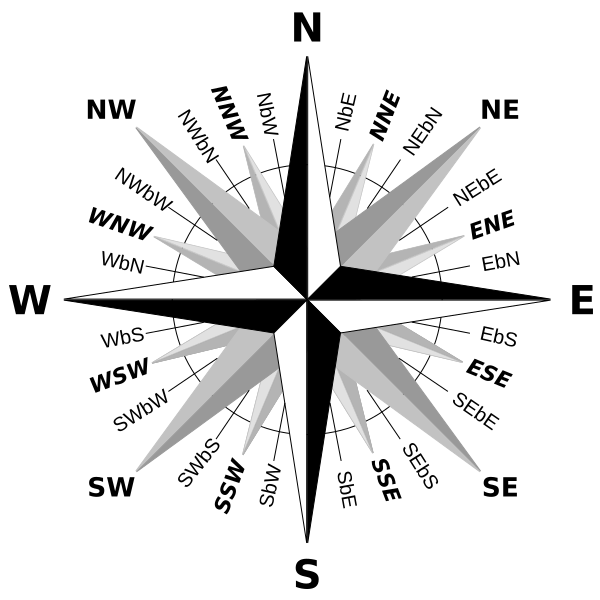

Write your Matlab code calculations and then assign them to a matrix T:

%% Calculations go here and then
% T = ????
theta = pi + 3*pi/8

theta = 4.3197

T = [cos(theta) -sin(theta) 123 
    sin(theta)  cos(theta)  -74.6
    0           0            1]

T =    -0.3827    0.9239  123.0000
   -0.9239   -0.3827  -74.6000
         0         0    1.0000


### Check your answer

assert(all(size(T)==3), 'The matrix must be 3x3');
R = T(1:2,1:2);
assert( abs(atan2d(R(2,1), R(1,1)) + 112.5) < 0.1, 'The rotation matrix is not correct, check your calculation of the heading SSW and whether you are using radians or degrees');
Tref = [-0.3827 0.9239 123; -0.9239 -0.3827 -74.6; 0 0 1];
assert( abs(atan2d(R(2,1), R(1,1)) + 112.5) < 0.1, 'The rotation matrix is not correct, check your calculation of the heading SSW and whether you are using radians or degrees')
assert(abs(sum(T(:)) - sum(Tref(:))) < 0.1, 'Incorrect calculated values')

## Exercise 4

The 2D pose of a robot, with respect to a world coordinate frame {O}, is described by a 3x3 homogeneous transform matrix T. A landmark point is described by a 2x1 coordinate vector P with respect to the world coordinate frame. What is the coordinate of the landmark with respect to the robot?

Given the homogeneous  matrix T and the vector P, write your matlab code calculations based on them and then assign them to a matrix called Result:

theta = 3*pi/8

theta = 1.1781

T = [cos(theta) -sin(theta) 55 
    sin(theta)  cos(theta)  100
    0           0            1]

T =     0.3827   -0.9239   55.0000
    0.9239    0.3827  100.0000
         0         0    1.0000



P = [0.5
     3.2]

P =     0.5000
    3.2000



%% Your calculations go here, make your computations
%  based on the above matrices T and P 
% 1. Calculate the rotation matrix from T and assign it to variable R
% 2. Calculate the translation matrix from T and assign it to variable t
% 3. and then:
% Result = ????

% **** Solution ****

% Rotation matrix
R = T(1:2, 1:2);

% translation matrix
t = T(1:2, 3)

t =     55
   100



Result = R'*(P - t)

Result =  -110.2878
   13.3077


### Check your answer

assert(all(size(Result) == [2 1]), 'The point should be described by a 2x1 vector')
PBref = R'*P - R'*t;
assert( all(abs(Result-PBref) < 0.001), 'The relative coordinates calculations are not correct')